clear;clc;

% load parameters
par = importdata('par_scg.txt');
par = par.data;

% initial values
y0 = zeros(4, 1);
y0(1) = 100000;
y0(4) = 100;

tmax = 400;
tspan = 0:0.1:tmax;

[~, y] = ode15s(@ODE_SCG, tspan, y0, [], par);

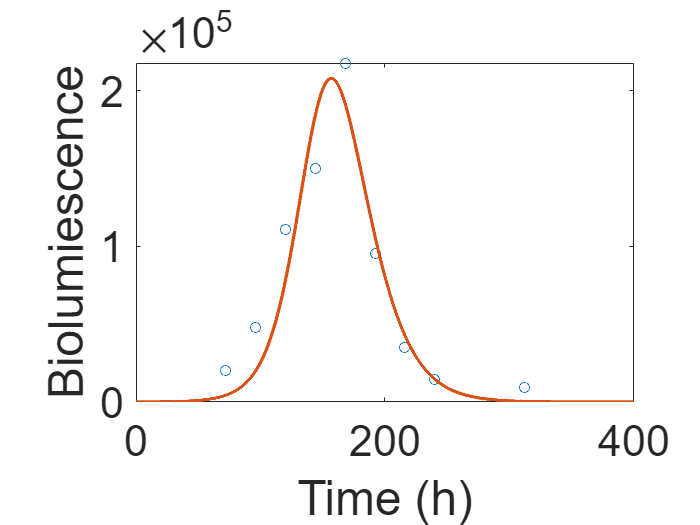

data = importdata('data.txt');
data(:, 1) = data(:, 1) .* 24;  % from day to hour

figure; hold on; set(gca,'Fontsize',26); box on;
scatter(data(:, 1), data(:, 2));
plot(tspan, y(:, 4), 'LineWidth', 2);
% set(gca, 'YScale', 'log');
xlabel('Time (h)'); ylabel('Biolumiescence');

% legend('Exp:clock KO', 'Simulation');